% Name: Guy Hasewinkel
% Student Number: HSWGUY001

% Loading specific CSV file into Simulink
% Matlab defined function used: https://www.mathworks.com/help/matlab/ref/matlab.io.spreadsheet.spreadsheetimportoptions.html
"\P45 - Pitch Rate - 1.xls"

ans = "\P45 - Pitch Rate - 1.xls"


"\P45 - Roll Rate - 5.xls"

ans = "\P45 - Roll Rate - 5.xls"



location="\P45 - Roll - 2.xls"

location = "\P45 - Roll - 2.xls"



opts = detectImportOptions(location);
opts.Sheet = 'Sheet1';
OrientationData = readmatrix(location,opts);
time = OrientationData(:,1);
Thrust = OrientationData(:,2);
Thrust = [time,Thrust];
Roll= OrientationData(:,3);
Roll=[time,Roll];
Pitch= OrientationData(:,4);
Pitch=[time,Pitch];
Yaw= OrientationData(:,5);
Yaw=[time,Yaw];
EstimateRoll= OrientationData(:,6);
EstimateRoll=[time,EstimateRoll];
EstimatePitch= OrientationData(:,7);
EstimatePitch=[time,EstimatePitch];
EstimateYaw= OrientationData(:,8);
EstimateYaw=[time,EstimateYaw];
optsRate = detectImportOptions(location);  

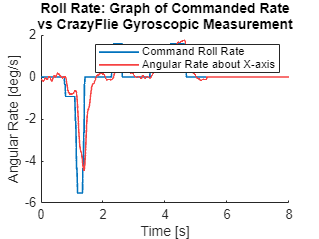

% ROLL RATE ANALYSIS
figure(1),clf
hold on
p_cmd = out.RollRate.data;
t_cmd = out.RollRate.Time;
p_actual = out.gyrox.data;
t_actual = out.gyrox.Time;
p = out.p.data;
t_p=out.p.Time;
plot(t_cmd,p_cmd,'Linewidth', 1.2,"Color",	"#0072BD")
plot(t_actual, p_actual,'Linewidth', 1.2,"Color","#F64242")
legend({'Command Roll Rate', 'Angular Rate about X-axis'}, 'Location', 'northeast')
title({'Roll Rate: Graph of Commanded Rate'; 'vs CrazyFlie Gyroscopic Measurement'})
xlabel('Time [s]')
ylabel('Angular Rate [deg/s]')
hold off

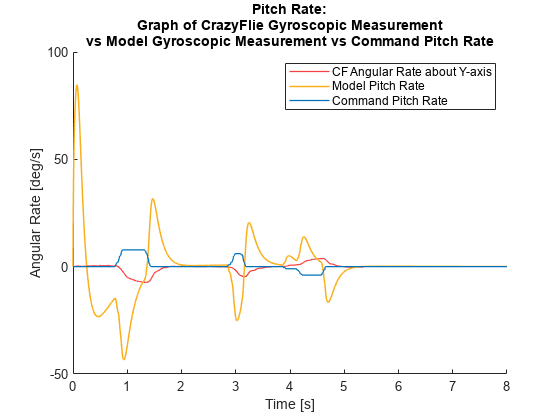

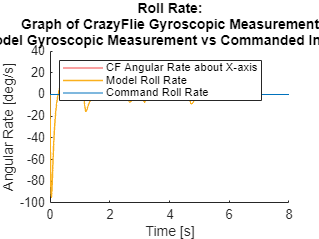

figure (2), clf
hold on
plot(t_actual,p_actual,'Linewidth', 0.9,"Color","#F64242")
plot(t_p,p,'Linewidth', 1.1,"Color",	"#FAB01D")
plot(t_cmd,p_cmd,'Linewidth', 0.9,"Color",	"#0072BD");
legend({'CF Angular Rate about X-axis', 'Model Roll Rate','Command Roll Rate'}, 'Location', 'northwest')
title({'Roll Rate:';'Graph of CrazyFlie Gyroscopic Measurement'; 'vs Model Gyroscopic Measurement vs Commanded Input Rate'})
xlabel('Time [s]')
ylabel('Angular Rate [deg/s]')
hold off

Gyro=lsiminfo(p_actual,t_actual,0,0,"SettlingTimeThreshold",0.15)

Gyro = struct with fields:
    TransientTime: 4.7849
     SettlingTime: 5.3500
              Min: -4.4563
          MinTime: 1.3900
              Max: 1.7538
          MaxTime: 4.6200


Command=lsiminfo(p_cmd,t_cmd,0,0,"SettlingTimeThreshold",0.15)

Command = struct with fields:
    TransientTime: 4.6428
     SettlingTime: NaN
              Min: -5.5266
          MinTime: 1.1820
              Max: 1.5801
          MaxTime: 2.3500


Model=lsiminfo(p,t_p,0,0,"SettlingTimeThreshold",0.10)

Model = struct with fields:
    TransientTime: 1.6571
     SettlingTime: NaN
              Min: -94.6742
          MinTime: 0.0460
              Max: 23.6990
          MaxTime: 1.4780


OvershootwrtCommand=abs(100*(Gyro.Max-Command.Max)/(Command.Max))

OvershootwrtCommand = 10.9964

UndershootwrtCommand=2*(Gyro.Min-Command.Min)/(abs(Gyro.Min)+abs(Command.Min))

UndershootwrtCommand = 0.2144

OvershootwrtModel=abs(100*(Gyro.Max-Model.Max)/(Model.Max))

OvershootwrtModel = 92.5996

UndershootwrtModel=2*(Gyro.Min-Model.Min)/(abs(Gyro.Min)+abs(Model.Min))

UndershootwrtModel = 1.8202

ModelOvershootwrtCommand=abs(100*(Model.Max-Command.Max)/(Command.Max))

ModelOvershootwrtCommand = 1.3999e+03

ModelUndershootwrtCommand=2*(Model.Min-Command.Min)/(abs(Gyro.Min)+abs(Command.Min))

ModelUndershootwrtCommand = -17.8600

TransientTimeGyro=Gyro.TransientTime

TransientTimeGyro = 4.7849

TransientTimeModel=Model.TransientTime

TransientTimeModel = 1.6571

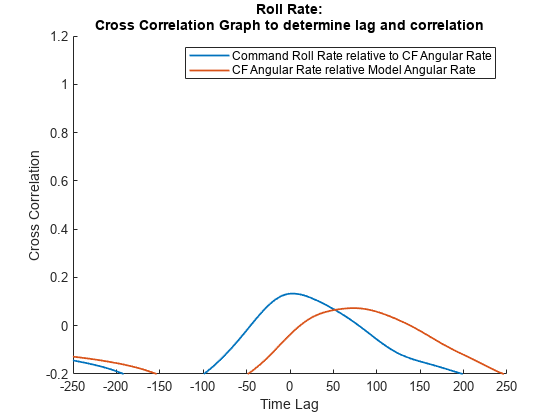

figure(3),clf
hold on
% Matlab defined function used: https://www.mathworks.com/help/matlab/ref/xcorr.html
[c,lags] = xcorr(p_cmd,p,'normalized');
plot(lags,c,'linewidth',1.3)
[cc,lagss] = xcorr(p_actual,p,'normalized');
plot(lagss,cc,'linewidth',1.3)
axis([-250 250 -0.2 1.2])
legend({'Command Roll Rate relative to CF Angular Rate', 'CF Angular Rate relative Model Angular Rate'}, 'Location', 'northeast')
title({'Roll Rate:'; 'Cross Correlation Graph to determine lag and correlation'})
xlabel('Time Lag')
ylabel('Cross Correlation')
hold off

[R,P] = corrcoef(p_actual,p);
PearsonR=R(1,2)

PearsonR = -0.0368

% PITCH RATE ANALYSIS
figure(1),clf
hold on
q_cmd = out.PitchRate.data;
t_cmd = out.PitchRate.Time;
q_actual = out.gyroy.data;
t_actual = out.gyroy.Time;
q = out.q.data;
t_q=out.q.Time;
plot(t_cmd,q_cmd,'Linewidth', 1.2,"Color",	"#0072BD");
plot(t_actual, q_actual,'Linewidth', 1.2,"Color","#F64242");
legend({'Command Pitch Rate', 'CF Angular Rate about Y-axis'}, 'Location', 'northeast')
title({'Pitch Rate: Graph of Commanded Rate'; 'vs CrazyFlie Gyroscopic Measurement'})
xlabel('Time [s]')
ylabel('Angular Rate [deg/s]')
hold off
figure (2), clf
%subplot(2,1,2);
hold on
plot(t_actual,q_actual,'Linewidth', 0.9,"Color","#F64242")
plot(t_q,q,'Linewidth', 1.1,"Color",	"#FAB01D")
plot(t_cmd,q_cmd,'r', 'Linewidth', 0.9,"Color",	"#0072BD");
legend({'CF Angular Rate about Y-axis', 'Model Pitch Rate','Command Pitch Rate'}, 'Location', 'northeast')
title({'Pitch Rate:'; 'Graph of CrazyFlie Gyroscopic Measurement'; 'vs Model Gyroscopic Measurement vs Command Pitch Rate'})
xlabel('Time [s]')
ylabel('Angular Rate [deg/s]')
hold off
Gyro=lsiminfo(q_actual,t_actual,0,0,"SettlingTimeThreshold",0.15)

Gyro = struct with fields:
    TransientTime: 4.8019
     SettlingTime: 5.3500
              Min: -7.3210
          MinTime: 1.3300
              Max: 3.7529
          MaxTime: 4.5600


Command=lsiminfo(q_cmd,t_cmd,0,0,"SettlingTimeThreshold",0.15)

Command = struct with fields:
    TransientTime: 4.6426
     SettlingTime: 4.6500
              Min: -3.9210
          MinTime: 4.2200
              Max: 7.8293
          MaxTime: 0.9120


Model=lsiminfo(q,t_q,0,0,"SettlingTimeThreshold",0.10)

Model = struct with fields:
    TransientTime: 4.8405
     SettlingTime: NaN
              Min: -43.4185
          MinTime: 0.9360
              Max: 84.6190
          MaxTime: 0.0740


OvershootwrtCommand=abs(100*(Gyro.Max-Command.Max)/(Command.Max))

OvershootwrtCommand = 52.0656

UndershootwrtCommand=2*(Gyro.Min-Command.Min)/(abs(Gyro.Min)+abs(Command.Min))

UndershootwrtCommand = -0.6049

OvershootwrtModel=abs(100*(Gyro.Max-Model.Max)/(Model.Max))

OvershootwrtModel = 95.5649

UndershootwrtModel=2*(Gyro.Min-Model.Min)/(abs(Gyro.Min)+abs(Model.Min))

UndershootwrtModel = 1.4229

ModelOvershootwrtCommand=abs(100*(Model.Max-Command.Max)/(Command.Max))

ModelOvershootwrtCommand = 980.7987

ModelUndershootwrtCommand=2*(Model.Min-Command.Min)/(abs(Gyro.Min)+abs(Command.Min))

ModelUndershootwrtCommand = -7.0268

TransientTimeGyro=Gyro.TransientTime

TransientTimeGyro = 4.8019

TransientTimeModel=Model.TransientTime

TransientTimeModel = 4.8405

figure(3),clf
hold on
[c,lags] = xcorr(q_cmd,q_actual,'normalized');
plot(lags,c,'linewidth',1.3)
[cc,lagss] = xcorr(q_actual,q,'normalized');
plot(lagss,cc,'linewidth',1.3)
axis([-250 250 -0.2 1.2])
legend({'Command Pitch Rate relative to CF Angular Rate', 'CF Angular Rate relative Model Angular Rate'}, 'Location', 'northeast')
title({'Pitch Rate:'; 'Cross Correlation Graph to determine lag and correlation'})
xlabel('Time Lag')
ylabel('Cross Correlation')
hold off
[R,P] = corrcoef(q_actual,q);
PearsonR=R(1,2)

% ATTITUDE ANALYSIS

%Roll Analysis
figure(1),clf
hold on
phi = out.Phi.data;
phi_t = out.Phi.Time;
phi_CMD = out.RollCMD.data;
phi_CMD_t = out.RollCMD.time;
phi_Estimate=out.RollEstimate.data;
phi_Estimate_t=out.RollEstimate.time;
plot(phi_CMD_t,phi_CMD,'Linewidth', 1.2,"Color",	"#0072BD")
plot(phi_Estimate_t, phi_Estimate,'Linewidth', 1.2,"Color","#F64242")
legend('Command Roll', 'CF Roll')
title({'Roll:';'Graph of CrazyFlie Attitude'; 'vs Model Attitude'})
xlabel('Time [s]')
ylabel('Angular Rate [deg]')
hold off
figure(2), clf
hold on
plot(phi_CMD_t,phi_CMD,'Linewidth', 1.2,"Color",	"#0072BD")
plot(phi_t,phi,'Linewidth', 1.4,"Color",	"#F7B722")
plot(phi_Estimate_t,phi_Estimate,'Linewidth', 1.2,"Color","#F64242")
legend('Command Roll', 'Model Roll','CF Roll','Location', 'northwest')
title({'Roll:';'Graph of Attitude Command'; 'vs Model Attitude vs CF Attitude'})
xlabel('Time [s]')
ylabel('Roll Angle [deg]')
hold off
Gyro=lsiminfo(phi_Estimate,phi_Estimate_t,0,0,"SettlingTimeThreshold",0.15)
Command=lsiminfo(phi_CMD,phi_CMD_t,0,0,"SettlingTimeThreshold",0.15)
Model=lsiminfo(phi,phi_t,0,0,"SettlingTimeThreshold",0.10)
OvershootwrtCommand=100*(Gyro.Max-Command.Max)/(Command.Max)
UndershootwrtCommand=2*(Gyro.Min-Command.Min)/(abs(Gyro.Min)+abs(Command.Min))
OvershootwrtModel=abs(100*(Gyro.Max-Model.Max)/(Model.Max))
UndershootwrtModel=2*(Gyro.Min-Model.Min)/(abs(Gyro.Min)+abs(Model.Min))
ModelOvershootwrtCommand=abs(100*(Model.Max-Command.Max)/(Command.Max))
ModelUndershootwrtCommand=2*(Model.Min-Command.Min)/(abs(Gyro.Min)+abs(Command.Min))
TransientTimeGyro=Gyro.TransientTime
TransientTimeModel=Model.TransientTime
figure(3),clf
hold on
[c,lags] = xcorr(phi_CMD,phi,'normalized');
plot(lags,c,'linewidth',1.3)
[cc,lagss] = xcorr(phi_Estimate,phi,'normalized');
plot(lagss,cc,'linewidth',1.3)
axis([-250 250 -0.2 1.2])
legend({'Command Roll relative to CF Roll', 'CF Roll relative Model Roll'}, 'Location', 'northeast')
title({'Pitch:'; 'Cross Correlation Graph to determine lag and correlation'})
xlabel('Time Lag')
ylabel('Cross Correlation')
hold off
[R,P] = corrcoef(phi_Estimate,phi);
PearsonR=R(1,2)

%Pitch Analysis
figure(1),clf
hold on
theta = out.Theta.data;
theta_t = out.Theta.Time;
theta_CMD = out.PitchCMD.data;
theta_CMD_t = out.PitchCMD.time;
theta_Estimate=out.PitchEstimate.data;
theta_Estimate_t=out.PitchEstimate.time;
plot(theta_CMD_t,theta_CMD,'Linewidth', 1.2,"Color",	"#0072BD")
plot(theta_Estimate_t, theta_Estimate,'Linewidth', 1.2,"Color","#F64242")
legend('Command Pitch', 'CF Pitch')
title({'Pitch:';'Graph of CrazyFlie Attitude'; 'vs Command Attitude'})
xlabel('Time [s]')
ylabel('Tait-Bryan Angle  [deg]')
hold off
figure(2), clf
hold on
plot(theta_CMD_t,theta_CMD,'Linewidth', 1.2,"Color",	"#0072BD")
plot(theta_t,theta,'Linewidth', 1.3,"Color",	"#F7B722")
plot(theta_Estimate_t,theta_Estimate,'Linewidth', 1.2,"Color","#F64242")
legend('Command Pitch', 'Model Pitch','CF Pitch','Location','northwest')
title({'Pitch:';'Graph of Attitude Command'; 'vs Model Attitude vs CF Attitude'})
xlabel('Time [s]')
ylabel('Pitch Angle [deg]')
hold off
Gyro=lsiminfo(theta_Estimate,theta_Estimate_t,0,0,"SettlingTimeThreshold",0.15)
Command=lsiminfo(theta_CMD,theta_CMD_t,0,0,"SettlingTimeThreshold",0.15)
Model=lsiminfo(theta,theta_t,0,0,"SettlingTimeThreshold",0.10)
OvershootwrtCommand=100*(Gyro.Max-Command.Max)/(Command.Max)
UndershootwrtCommand=2*(Gyro.Min-Command.Min)/(abs(Gyro.Min)+abs(Command.Min))
OvershootwrtModel=abs(100*(Gyro.Max-Model.Max)/(Model.Max))
UndershootwrtModel=2*(Gyro.Min-Model.Min)/(abs(Gyro.Min)+abs(Model.Min))
ModelOvershootwrtCommand=abs(100*(Model.Max-Command.Max)/(Command.Max))
ModelUndershootwrtCommand=2*(Model.Min-Command.Min)/(abs(Gyro.Min)+abs(Command.Min))
TransientTimeGyro=Gyro.TransientTime
TransientTimeModel=Model.TransientTime
figure(3),clf
hold on
[c,lags] = xcorr(theta_CMD,theta,'normalized');
plot(lags,c,'linewidth',1.3)
[cc,lagss] = xcorr(theta_Estimate,theta,'normalized');
plot(lagss,cc,'linewidth',1.3)
axis([-250 250 -0.2 1.2])
legend({'Command Pitch relative to CF Pitch', 'CF Pitch relative Model Pitch'}, 'Location', 'northeast')
title({'Pitch:'; 'Cross Correlation Graph to determine lag and correlation'})
xlabel('Time Lag')
ylabel('Cross Correlation')
hold off
[R,P] = corrcoef(theta_Estimate,theta);
PearsonR=R(1,2)

%Yaw Analysis
figure(1),clf
hold on
psi = out.Psi.data;
psi_t = out.Psi.Time;
psi_CMD = out.YawCMD.data;
psi_CMD_t = out.YawCMD.time;
psi_Estimate=out.YawEstimate.data;
psi_Estimate_t=out.YawEstimate.time;
plot(psi_CMD_t,psi_CMD,'Linewidth', 1.2,"Color",	"#0072BD")
plot(psi_Estimate_t, psi_Estimate,'Linewidth', 1.2,"Color","#F64242")
legend('Command Yaw', 'CF Yaw')
title({'Yaw:';'Graph of CrazyFlie Attitude'; 'vs Model Attitude'})
xlabel('Time [s]')
ylabel('Tait-Bryan Angle [deg]')
hold off
figure(2), clf
hold on
plot(psi_CMD_t,psi_CMD,'Linewidth', 1.2,"Color",	"#0072BD")
plot(psi_t,psi,'Linewidth', 0.9,"Color",	"#F7B722")
plot(psi_Estimate_t,psi_Estimate,'Linewidth', 1.2,"Color","#F64242")
legend('Command Yaw', 'Model Yaw','CF Yaw')
title({'Yaw:';'Graph of Attitude Command'; 'vs Model Attitude vs CF Attitude'})
xlabel('Time [s]')
ylabel('Yaw Angle  [deg]')
hold off
figure(3),clf
hold on
[c,lags] = xcorr(psi_CMD,psi,'normalized');
plot(lags,c,'linewidth',1.3)
[cc,lagss] = xcorr(psi_Estimate,psi,'normalized');
plot(lagss,cc,'linewidth',1.3)
axis([-250 250 -0.2 1.2])
legend({'Command Yaw relative to CF Yaw', 'CF Yaw relative Model Yaw'}, 'Location', 'northeast')
title({'Yaw: Cross Correlation Graph to determine lag and correlation'})
xlabel('Time Lag')
ylabel('Cross Correlation')
hold off
[R,P] = corrcoef(psi_Estimate,psi);
PearsonR=R(1,2)
Gyro=lsiminfo(psi_Estimate,psi_Estimate_t,0,0,"SettlingTimeThreshold",0.15)
Command=lsiminfo(psi_CMD,psi_CMD_t,0,0,"SettlingTimeThreshold",0.15)
Model=lsiminfo(psi,psi_t,0,0,"SettlingTimeThreshold",0.10)
OvershootwrtCommand=100*(Gyro.Max-Command.Max)/(Command.Max)
UndershootwrtCommand=2*(Gyro.Min-Command.Min)/(abs(Gyro.Min)+abs(Command.Min))
OvershootwrtModel=abs(100*(Gyro.Max-Model.Max)/(Model.Max))
UndershootwrtModel=2*(Gyro.Min-Model.Min)/(abs(Gyro.Min)+abs(Model.Min))
ModelOvershootwrtCommand=abs(100*(Model.Max-Command.Max)/(Command.Max))
ModelUndershootwrtCommand=2*(Model.Min-Command.Min)/(abs(Gyro.Min)+abs(Command.Min))

%Attitude Integral Wind Up Analysis
figure(1), clf
hold on
plot(out.PitchIntegrator.Time,out.PitchIntegrator.data)
legend({'Integrator Wind Up Error'}, 'Location', 'east')
title({'Pitch:';'Integrator Wind Up Error'})
xlabel('Time [s]')
ylabel('Motor Command Input - PWM/Gain')
hold off
figure(2), clf
hold on
plot(out.RollIntegrator.Time,out.RollIntegrator.data)
legend({'Integrator Wind Up Error'}, 'Location', 'northeast')
title({'Roll:';'Integrator Wind Up Error'})
xlabel('Time [s]')
ylabel('Motor Command Input - PWM/Gain')
hold off
hold on
figure(3),clf
plot(out.YawIntegrator.Time,out.YawIntegrator.data)
legend({'Integrator Wind Up Error'}, 'Location', 'northeast')
title({'Yaw:';'Integrator Wind Up Error'})
xlabel('Time [s]')
ylabel('Motor Command Input - PWM/Gain')
hold off

% SIMULATED COMMAND

% Step Analysis
figure(1),clf
hold on
plot(out.p.Time,out.p.data, 'Linewidth',1.2)
plot(out.q.Time,out.q.data, 'Linewidth',1.2)
plot(out.r.Time,out.r.data, 'Linewidth',1.2)
plot(out.STEP.Time, out.STEP.data, 'Linewidth',1.4)
%legend('Command Pitch', 'CF Pitch')
title({'Combined Step Input Rate Command:';'Graph of Model Attitude Rate vs Command Input Rate'})
legend({'Roll Rate','Pitch Rate','Yaw Rate','Input Rate Command'}, 'Location', 'east')
xlabel('Time [s]')
ylabel('Attitude [deg/s]')
hold off
SInfo = stepinfo(out.p.data,out.p.Time);
SettlingT = SInfo.TransientTime
PeakT = SInfo.PeakTime

%stepinfo(out.RollRate.data,out.RollRate.Time,0,0)
%lsiminfo(out.RollRate.data,out.RollRate.Time)
% y = out.p.data
% t=out.p.Time
% threshold=0.02
% stepResults = stepinfo(y,t,'SettlingTimeThreshold',threshold);
% indexSettling = find(t>=stepResults.SettlingTime,1);
% hold on;
% plot(t(indexSettling),y(indexSettling),'ro');
% plot([0 t(indexSettling)],[y(indexSettling) y(indexSettling)],'k-.');
% plot([t(indexSettling) t(indexSettling)],[0 y(indexSettling)],'k-.');
% text(stepResults.SettlingTime+0.1,0.9,['t_s \approx ',num2str(stepResults.SettlingTime),' sec']);
% plot(stepResults.PeakTime,stepResults.Peak,'ro');
% plot([stepResults.PeakTime stepResults.PeakTime], [0 stepResults.Peak],'k-.');
% plot([0 stepResults.PeakTime], [stepResults.Peak stepResults.Peak],'k-.');
% text(stepResults.PeakTime+0.1,0.1,['t_p = ',num2str(stepResults.PeakTime),' sec']);
% text(stepResults.PeakTime+0.1,stepResults.Peak+0.03,['M_p = ',num2str(stepResults.Overshoot),'%']);
% hold off;